# Finite Element Formulation of the linear Reissner-Mindlin Plate

## Introduction

In this section it is considered a shear-deformable plate that is fixed along a portion of its boundary (Dirichlet boundary conditions) whereas distributed/boundary forces/monents are applied within/along a portion of its surface/boundary, see the following figure accordingly:

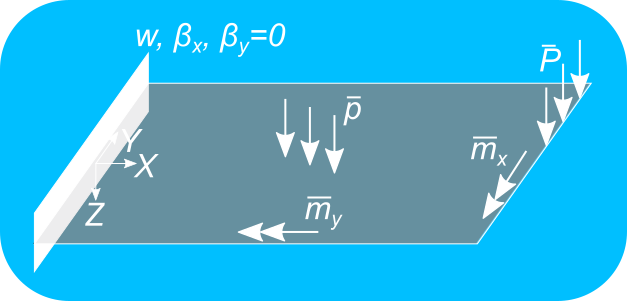

This kind of problem can be mathematically described using the Reissner-Mindlin plate theory. The primal uknown fields of the Reissner-Mindlin plate are the vertical deflection field $w$ and the two total cross-sectional rotation fields $\beta_x,\beta_y$ around the x- and the y-axes, respectively. The underlying Partial Differential Equation (PDE), or Boundary Value Problem (BVP), or equivalently strong formulation of the problem writes as follows:


$$\begin{array}{lll}
\frac{\partial q_x}{ \partial x} + \frac{\partial q_y}{ \partial y} + \bar{p} = 0, & \text{in} \: \Omega, & \text{(1.1)} \\
-\frac{\partial m_y}{ \partial y} + \frac{\partial m_{xy}}{ \partial x} + q_y = 0, & \text{in} \: \Omega, & \text{(1.2)} \\
\frac{\partial m_x}{ \partial x} + \frac{\partial m_{yx}}{ \partial y} - q_x = 0, & \text{in} \: \Omega, & \text{(1.3)} \\
q_x n_x + q_y n_y = \bar{P}, & \text{on} \: \subset \partial \Omega, & \text{(1.4)} \\
m_{xy} n_x + m_y n_y = - \bar{M_x}, & \text{on} \: \subset \partial \Omega, & \text{(1.4)} \\
m_x n_x + m_{xy} n_y = \bar{M_y}, & \text{on} \: \subset \partial \Omega, & \text{(1.4)} \\
\end{array}$$


The corresponding strains are the shear deformations of the cross sections $\gamma_x,\gamma_y$ and the change in the curvature second-order tensor $\kappa_x,\kappa_y,\kappa_{xy}$ and they given by the following expressions:


$$\begin{array}{ll}
\gamma_x = \frac{\partial w}{\partial x} + \beta_y = w_{,x} + \beta_y & \text{(2.1)} \\
\gamma_y = \frac{\partial w}{\partial y} - \beta_x = w_{,y} - \beta_x  & \text{(2.2)} \\
\kappa_x = \frac{\partial \beta_x}{\partial y} = \beta_{x,y} & \text{(2.3)} \\
\kappa_y = \frac{\partial \beta_y}{\partial x} = \beta_{y,x} & \text{(2.4)} \\
\kappa_{xy} =  \frac{1}{2} \left( \frac{\partial \beta_y}{\partial y} - \frac{\partial \beta_x}{\partial x} \right) = \frac{1}{2} \left( \beta_{y,y} - \beta_{x,x} \right) & \text{(2.5)}
\end{array}$$


Then, the constitutive equations are given by the following relations:


$$\begin{array}{ll}
q_x = \alpha G t \gamma_x & \text{(3.1)} \\
q_y = \alpha G t \gamma_y & \text{(3.2)} \\
m_x = D \left( \kappa_x + \nu \kappa_y \right) & \text{(3.3)} \\
m_y = D \left( \kappa_y + \nu \kappa_x \right) & \text{(3.4)} \\
m_{xy} = D \left( 1 - \nu \right) k_{xy} , & \text{(3.5)}
\end{array}$$


Finally, the weak formulation of the problem writes as follows:


$$\begin{array}{ll}
\delta W_{\text{int}} + \delta W_{\text{ext}} = 0, & \text{(4.1)} \\
-\delta W_{\text{int}} = \int_{A} q_x \: \delta \gamma_x + q_y \: \delta \gamma_y + m_x \: \delta \kappa_x + m_y \: \delta \kappa_y + m_{xy} \: \delta \kappa_{xy} \: \text{d} A , & \text{(4.2)} \\
\delta W_{\text{ext}} = \int_{A} \bar{p} \delta w \: \text{d} A + \int_{\subset\partial A} \bar{M}_x \: \delta \beta_x \: \text{d} \partial A + \int_{\subset\partial A} \bar{M}_y \: \delta \beta_y \: \text{d} \partial A . & \text{(4.3)}
\end{array}$$


The problem under study herein is a cantilever plate subject to a distributed vertical load, see the following figure,

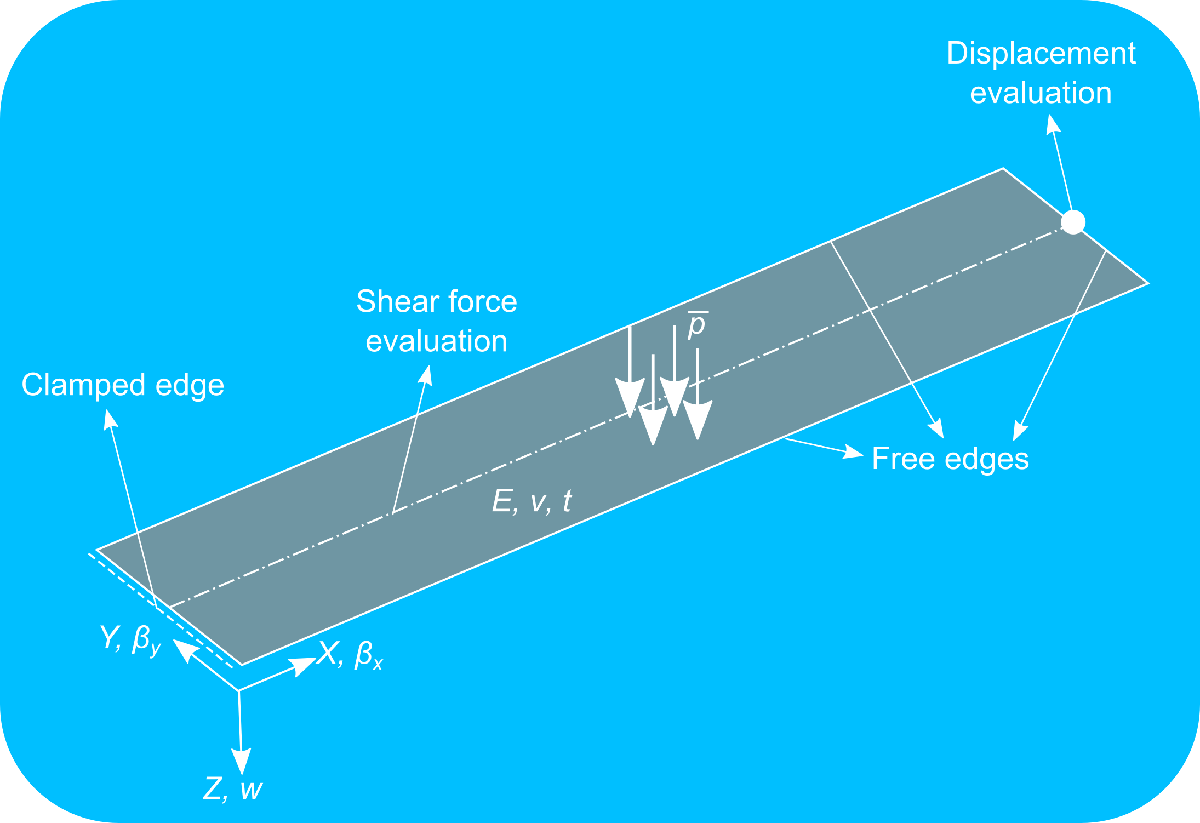

It is herein developed a Finite Element formulation for the Reissner-Mindlin plate theory and it is tested using both linear and bilinear basis functions. The solution of the problem setup depicted above along the $X$-direction is identical to the solution of the problem discussed in Live Script [main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')), namely, the cantilever beam subject to a distributed vertical load. This solution is then invariant of the $Y$-location, since their is no variation of the solution along the $Y$-direction due to the given boundary conditions and geometry. Under these circumnstances the analytical solution of the problem can be "borrowed" by the equivalent Timoshenko cantilever beam which is presented [here](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')), namely:


$$w(X,Y) = \frac{1}{\alpha G A} \left( \overline{p} L X - \frac{\overline{p} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{p} X^4}{24} + \frac{\overline{p} L X^3}{6} - \frac{\overline{p} L^2 X^2}{4} \right) \qquad (5)$$


When substituting both the material and the kinematics relationships in the differential equation governing the Timoshenko beam problem, the final set of differential equations is the following one:


$$\overline{p} + \alpha G A \left( \frac{\partial^2 w}{\partial X^2} + \frac{\partial \beta_y}{\partial X} \right) = 0 \qquad (6.1) \\
\overline{m} + EI \frac{\partial^2 \beta_y}{\partial X^2} = 0 \qquad \qquad \qquad \, (6.2) $$


where the notations for the Reissner-Mindin plate have been kept. Moreover, the rotation around the $X$-axis, namely $\beta_x$, is equal to zero under the particular boundary and loading conditions. Similar to the derivation of equation (7) [here](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')), substitung equation (1) into (2.1) and solving for $\beta$ results in the following expression:


$$\beta_y(X,Y) = \int_0^L - \frac{1}{\alpha G A} \overline{p} - \frac{\partial^2 w}{\partial X^2} \; \text{d} X \qquad (7)$$


The [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)® can be used to obtain an analytical expression for equation (5) in only one line of code, see the corresponding code section.

[PREVIOUS Chapter](matlab:open('..\2_TimoshenkoBeam\main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) *Finite Element Formulation of the linear Timoshenko beam*

[NEXT Chapter](matlab:open('..\3_TransverseShearLocking\3_TransverseShearLocking_TimoshenkoBeam\main_Chapter3_TransverseShearLocking_TimoshenkoBeam.mlx')) *Transverse-Shear Locking in Timoshenko beam elements - Cantilever Beam Subject to Vertical Distributed Load*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem setup**

### Geometric parameters

Thickness [$m$]

propStr.t = 10^(-1);

X-coordinate of the left edge [$m$]

X0 = 0;

X-coordinate of the right edge [$m$]

XLx = 4;

Y-coordinate of the left edge [$m$]

Y0 = 0;

Y-coordinate of the right edge [$m$]

YLy = 1;

### Material paramerters

distributed load [$N/m^2$]

propStr.pBar = -3e4*(propStr.t)^3;

distributed moment around x-axis [$N$]

propStr.mxBar = 0;

distributed moment around y-axis [$N$]

propStr.myBar = 0;

Young's modulus [$N/m^2$]

propStr.E = 1e7;

Poisson ration [dimensionless]

propStr.nu = 0;

Shear modulus (connected to `epsilon_12 = E/(1+nu)`) [$N/m^2$]

propStr.G = propStr.E/2/(1 + propStr.nu);

Plate stiffness [$N\cdot m$]

propStr.D = propStr.E*propStr.t^3/12/(1 - propStr.nu^2);

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Derivation of the analytical solution using the Timoshenko beam formulation

Since the plate is rectangular, clamped on its one end while being subject to constant distributed vertical load its behavior is expected to resemble a beam aligned with the X-axis, whereas no effects are expected to take place along the Y-axis. The analytical solution for this problem using the shear-deformable Timoshenko beam formulation are in this case as follows

### Initialize auxiliary variables

syms wEx(X,Y) betaEx(X,Y) Q(X,Y) Lsym psym Gsym Aqsym Esym Isym

### Definition of the analytical solution regarding the vertical deflection and rotation field

Set the analytical solution in terms of the vertical deflection field (Eq. (1) in the introduction):


$$w(X,Y) = \frac{1}{\alpha G A} \left( \overline{p} L X - \frac{\overline{p} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{p} X^4}{24} + \frac{\overline{p} L X^3}{6} - \frac{\overline{p} L^2 X^2}{4} \right)$$


namely:

wEx(X,Y) = (psym*Lsym*X-psym*X^2/2)/Gsym/(Aqsym) - ...
    (-psym*X^4/24+psym*Lsym*X^3/6-psym*Lsym^2*X^2/4)/Esym/Isym;

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) in [MATLAB](https://www.mathworks.com/products/matlab.html)


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{p} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x$$


betaEx(X,Y) = int(-1/(propStr.alpha*propStr.G*YLy*propStr.t)*...
    propStr.pBar - diff(diff(wEx, X), X));

### Substitution of the known parameters in the analytical expression

wEx(X,Y) = subs(wEx,{Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, YLy*(propStr.t^3)/12, ...
    propStr.alpha*YLy*propStr.t});
betaEx(X,Y) = subs(betaEx,{Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, YLy*(propStr.t^3)/12, ...
    propStr.alpha*YLy*propStr.t});
Q(X,Y) = propStr.alpha*YLy*propStr.t*propStr.G*(betaEx(X,Y) + ...
    diff(wEx, X));

## **Basis functions**

### **Bilinear basis functions**


$$N_1^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 - \eta) \quad (\xi,\eta) \in [-1, 1]^2, \quad (8.1) \\
N_2^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 - \eta) \quad (\xi,\eta) \in [-1, 1]^2, \quad (8.2) \\
N_3^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 + \eta) \quad (\xi,\eta) \in [-1, 1],^2 \quad (8.3)\\
N_4^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 + \eta) \quad (\xi,\eta) \in [-1, 1]^2. \quad (8.4)$$
 

#### Definition

syms N1Q1(xi, eta) N2Q1(xi, eta) N3Q1(xi, eta) N4Q1(xi, eta)
N1Q1(xi, eta) = (1 - xi)*(1 - eta)/4;
N2Q1(xi, eta) = (1 + xi)*(1 - eta)/4;
N3Q1(xi, eta) = (1 + xi)*(1 + eta)/4;
N4Q1(xi, eta) = (1 - xi)*(1 + eta)/4;
NQ1 = {N1Q1 N4Q1 N3Q1 N2Q1};

#### Visual representation

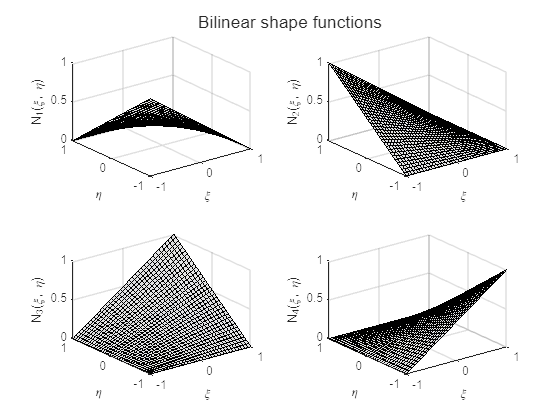

figure,
t1 = tiledlayout(2, 2);
title(t1, "Bilinear shape functions")
for ii = 1:numel(NQ1)
    nexttile
    fsurf(NQ1{ii}, [-1 1 -1 1], LineStyle='-', ...
        FaceColor=[217 218 219]/255, FaceAlpha=3/4);
    xlabel("\xi");
    ylabel("\eta");
    zlabel(strcat(sprintf("N_%i", ii),"(\xi, \eta)"));
end

### **Biquadratic basis Functions**


$$N_1^{Q_2}(\xi, \eta) = \frac{1}{4} \xi (\xi - 1) \eta (1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \, \quad(9.1) \\
N_2^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)\eta(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad(9.2) \\
N_3^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi \eta(\eta - 1) \quad (\xi,\eta) \in [0, 1],  \quad \quad \quad \, \quad(9.3) \\
N_4^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)\xi(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad(9.4) \\
N_5^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1],  \quad \quad \quad \, \quad(9.5) \\
N_6^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad(9.6) \\
N_7^{Q_2}(\xi, \eta) = \frac{1}{4}\xi (\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \, \quad(9.7) \\
N_8^{Q_2}(\xi, \eta) = -\frac{1}{2}\xi (\xi - 1)(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad(9.8) \\
N_9^{Q_2}(\xi, \eta) = \frac{1}{1}(1 - \xi^2) (1 - \eta^2)\quad (\xi,\eta) \in [0, 1]. \quad \quad \quad \; \, \quad(9.9)$$


#### **Definition**

syms N1Q2(xi, eta) N2Q2(xi, eta) N3Q2(xi, eta) N4Q2(xi, eta) ...
    N5Q2(xi, eta) N6Q2(xi, eta) N7Q2(xi, eta) N8Q2(xi, eta) ...
    N9Q2(xi, eta)
N1Q2(xi, eta) = xi*(xi - 1)*eta*(eta - 1)/4;
N2Q2(xi, eta) = (xi + 1)*(xi - 1)*eta*(eta - 1)/-2;
N3Q2(xi, eta) = (xi + 1)*xi*eta*(eta - 1)/4;
N4Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*(eta - 1)/-2;
N5Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*eta/4;
N6Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*eta/-2;
N7Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*eta/4;
N8Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*(eta - 1)/-2;
N9Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*(eta - 1)/1;
NQ2 = {N1Q2 N7Q2 N5Q2 N3Q2 N8Q2 N4Q2 N2Q2 N6Q2 N9Q2};

#### Visual representation

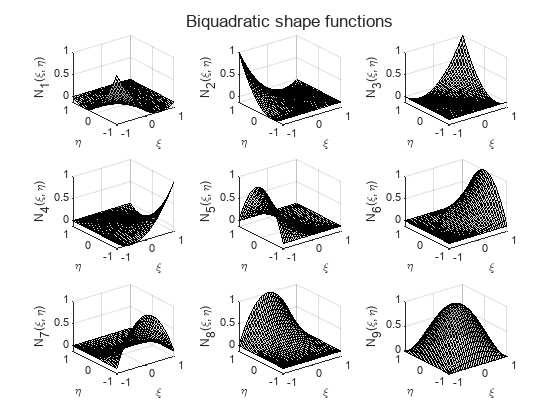

figure,
t1 = tiledlayout(3, 3);
title(t1, "Biquadratic shape functions")
for ii = 1:numel(NQ2)
    nexttile
    fsurf(NQ2{ii}, [-1 1 -1 1], LineStyle='-', ...
        FaceColor=[217 218 219]/255, FaceAlpha=3/4);
    xlabel("\xi");
    ylabel("\eta");
    zlabel(strcat(sprintf("N_%i", ii),"(\xi, \eta)"));
end

### **Linear triangular basis functions**


$$N_1^{T_1}(\xi, \eta) = \xi \quad (\xi,\eta) \in [-1, 1]^2 \text{ with } \xi + \eta \le 1, \quad \quad \quad \quad (10.1) \\
N_2^{T_1}(\xi, \eta) = \eta \quad (\xi,\eta) \in [-1, 1]^2 \text{ with } \xi + \eta \le 1, \quad \quad \quad \quad (10.2) \\
N_3^{T_1}(\xi, \eta) = 1 - \xi - \eta \quad (\xi , \eta) \in [-1, 1]^2 \text{ with } \xi + \eta \le 1 \quad (10.3)$$
 

#### Definition

syms N1T1(xi, eta) N2T1(xi, eta) N3T1(xi, eta)
N1T1(xi, eta) = xi;
N2T1(xi, eta) = eta;
N3T1(xi, eta) = 1 - xi- eta;
NT1 = {N1T1 N2T1 N3T1};

## **Basis functions derivatives**


$$N_{i,\xi}(\xi,\eta) = \frac{\partial N_i^{Q_1}(\xi,\eta)}{\partial \xi}, \quad (11.1) \\
N_{i,\eta}(\xi,\eta) = \frac{\partial N_i^{Q_1}(\xi,\eta)}{\partial \eta}. \quad (11.2)$$


### **Parametric derivatives of the bilinear basis functions**

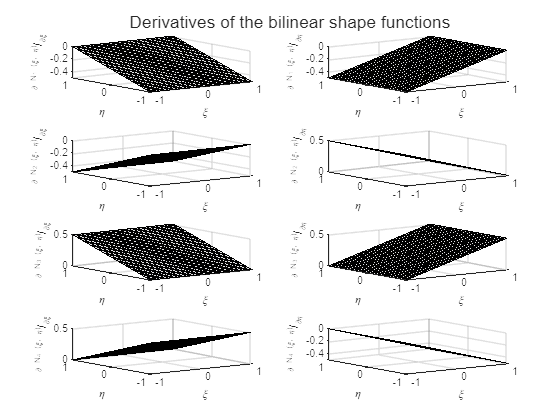

figure,
t2 = tiledlayout(4, 2);
paramSpace = [xi eta];
paramSpaceStr = {'\xi', '\eta'};
title(t2, "Derivatives of the bilinear shape functions")
for ii = 1:numel(NQ1)
    for jj = 1:2
        nexttile
        fsurf(diff(NQ1{ii}, paramSpace(jj)), [-1 1 -1 1], ...
            LineStyle='-', FaceColor=[217 218 219]/255, FaceAlpha=3/4);
        xlabel("\xi");
        ylabel("\eta");
        zlabel(sprintf("^{\\partial N_{%d} (\\xi, \\eta)}/_{\\partial%s}", ...
            ii, paramSpaceStr{jj}));
    end
end

### **Derivation of the parametric derivatives of the biquadratic basis functions**

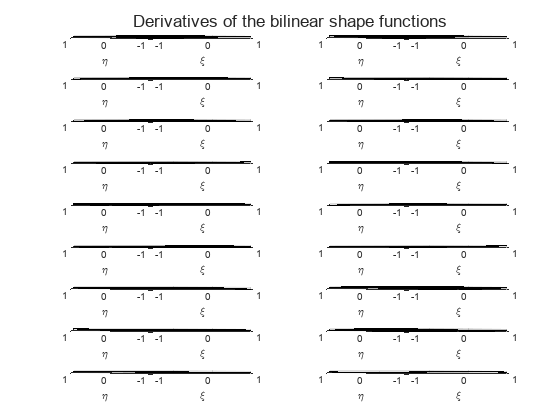

figure,
t2 = tiledlayout(9, 2);
paramSpace = [xi eta];
paramSpaceStr = {'\xi', '\eta'};
title(t2, "Derivatives of the bilinear shape functions")
for ii = 1:numel(NQ2)
    for jj = 1:2
        nexttile
        fsurf(diff(NQ2{ii}, paramSpace(jj)), [-1 1 -1 1], LineStyle='-', ...
            FaceColor=[217 218 219]/255, FaceAlpha=3/4);
        xlabel("\xi");
        ylabel("\eta");
        zlabel(sprintf("^{\\partial N_{%d} (\\xi, \\eta)}/_{\\partial%s}", ...
            ii, paramSpaceStr{jj}));
    end
end

## **Discretization**

Both the vertical deflection $w$ and cross-sectional rotation $\beta_x$, $\beta_y$ fields are discretized using the same basis (shape) functions, namely:


$$\begin{array}{l}
w\left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 1\right)\\
\beta_x \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{x,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 2\right)\\
\beta_y \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{y,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 3\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### Quadrilateral mesh

#### Choose number of elements in the mesh

Number of elements along the X-direction

numElx = 7;

Number of elements along the Y-direction

numEly = 2;

  **Try**

Change the number of elements along the $X$- and $Y$-Cartesian direction using the numeric slider for variable `numElx` and `numEly`, respectively.

 **Reflect**

What can you say about the solution of the bilinear quadrilateral and linear triangular elements as compared to the biquadratic quadrilateral elements?

#### Mesh generation

numEl = numElx*numEly;
[nodesX, nodesY] = generateQuadrilateralMesh ...
    (X0, XLx, Y0, YLy, numElx, numEly);

### **Four-noded bilinear quadrilateral mesh**

#### **Mesh generation**

numNodesElQ1 = 4;
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodesQ1 = numel(mshQ1.nodes(:, 1));

#### Rendering the mesh non-uniform

isMeshNonUniform = false;
if isMeshNonUniform % Move the nodes of the mesh randomly
    for ii = 1:numNodesQ1
        mshQ1.nodes(ii, 1:2) = mshQ1.nodes(ii, 1:2) + rand(1,2)/5;
    end
    nodesX = reshape(mshQ1.nodes(:, 1), height(nodesX), []);
    nodesY = mshQ1.nodes(:, 2);
end

#### Dirichlet boundary conditions for the mesh with the bilinear quadrilateral elements

numDOFsQ1 = 3*numNodesQ1;
[freeDOFsQ1, homDOFsQ1] = ...
    utilityFunctionsCantileverPlate.getFreeDOFsBilinearQuadrilateralMesh ...
    (numNodesQ1, numEly);
numVertices = numel(mshQ1.nodes(:, 1));

#### Mesh plot

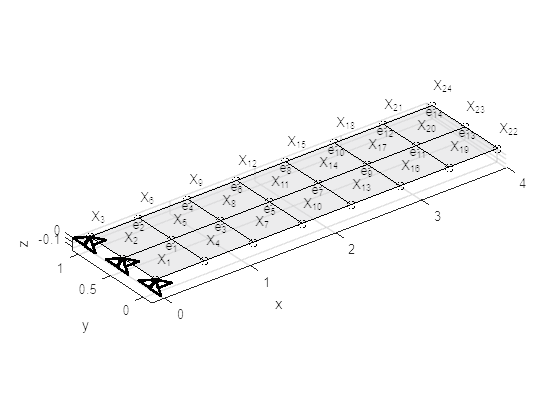

figure,
plotMesh2d(mshQ1, numVertices, true);
hold on;
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshQ1.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")

#### Display the mesh with the basis functions

isPlotBasisFunctions = false;
if isPlotBasisFunctions
    [h5, h6, h7] = plotMeshAndBasisFunctions2d(mshQ1, NQ1, true);
end

  **Try**

Use a non-uniform mesh by unselecting the checkbox in this code section.

 **Reflect**

Do you still expect a numerical solution from FEM that matches the analytical one?

  **Try**

Select the checkbox in this code section to create an animation for the bilinear basis functions throughout the mesh. Be aware that this code section can take very long to run due to rendering of complex graphics.

 **Reflect**

What is the support of the bilinear basis functions, namely, the area over which they are not identical zero?

### **Nine-noded biquadratic quadrilateral mesh**

#### **Mesh generation**

numNodesElQ2 = 9;
[mshQ2, ~] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, ...
    numNodesElQ1, numNodesElQ2);

#### Dirichlet boundary conditions for the mesh with the biquadratic quadrilateral elements

numNodesQ2 = numel(mshQ2.nodes(:, 1));
numDOFsQ2 = 3*numNodesQ2;
[freeDOFsQ2, homDOFsQ2] = ...
    utilityFunctionsCantileverPlate.getFreeDOFsBiquadraticQuadrilateralMesh ...
    (numNodesQ1, numNodesQ2, numEly);

#### Mesh plot

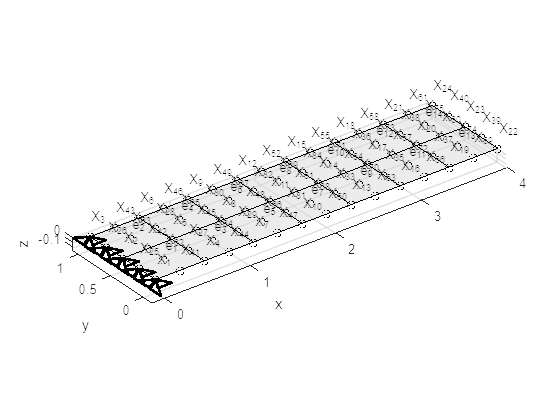

numVertices = numel(mshQ1.nodes(:, 1));
figure,
plotMesh2d(mshQ2, numVertices, true);
hold on;
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshQ2.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))    
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")

  **Try**

Change the number of elements in the mesh in this code section.

 **Reflect**

How is the solution affected by the different mesh densities?

### **Three-noded linear triangular mesh**

sz = size(nodesX);
mshT1 = generateLinearTriangularMeshOnQuadrilateralMesh(reshape(nodesX, [], 1), nodesY);

#### Dirichlet boundary conditions for the mesh with the linear triangular elements

if ~isempty(mshT1)
    numNodesT1 = numel(mshT1.nodes(:, 1));
    numDOFsT1 = 3*numNodesT1;
    xCoordDirichlet = [X0 X0];
    yCoordDirichlet = [Y0 Y0+YLy];
    [freeDOFsT1, homDOFsT1] = ...
        utilityFunctionsCantileverPlate.getFreeDOFsLinearTriagularMesh ...
        (mshT1, xCoordDirichlet, yCoordDirichlet);
end

#### Graphical representation of the mesh along the Dirichlet boundary conditions

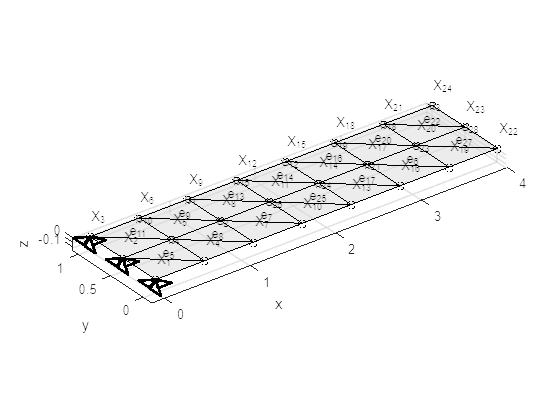

if ~isempty(mshT1)
    numVertices = height(mshT1.nodes);
    figure,
    plotMesh2d(mshT1, numVertices, true);
    hold on;
    scalVer = 1;
    [xsT1, ysT1, zsT1] = createSupports3D(mshT1.nodes, homDOFsT1, scalVer);
    for k = 1:length(xsT1(:, 1))
        plot3(xsT1(k, :), ysT1(k, :), zsT1(k, :), 'Linewidth', 2, ...
            'Color', 'black');
    end
    hold off;
    axis equal;
    xlabel("x")
    ylabel("y")
    zlabel("z")
end

## Master stiffness matrix and load vector

### Four-noded bilinear Reissner-Mindlin elements

computeStiffMatrixandForceVectorQ1 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ1 = NQ1;
[KQ1, FQ1] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ1, computeBasisFunctionsAndDerivsQ1, ...
    computeStiffMatrixandForceVectorQ1, propStr);

Visualization of the sparsity of the master global stiffness matrix

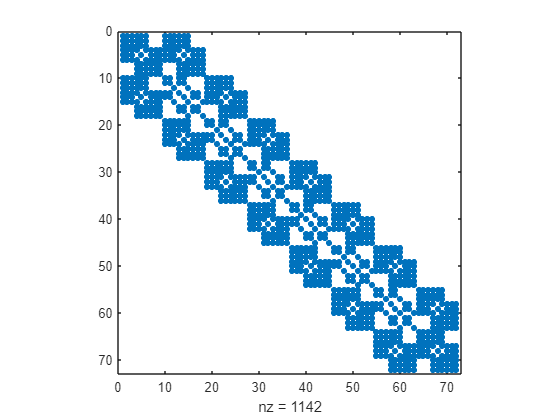

spy(KQ1)

### Nine-noded biquadratic Reissner-Mindlin elements

computeStiffMatrixandForceVectorQ2 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivs_Q2 = NQ2;
[KQ2, FQ2] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ2, computeBasisFunctionsAndDerivs_Q2, ...
    computeStiffMatrixandForceVectorQ2, propStr);

Visualization of the sparsity of the master stiffness matrix

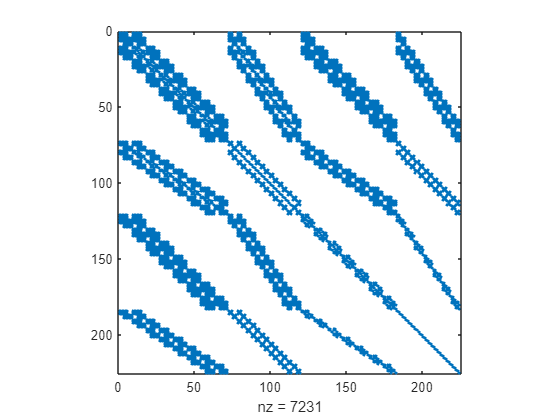

spy(KQ2)

### Three-noded linear Reissner-Mindlin elements

if ~isempty(mshT1)
    computeStiffMatrixandForceVectorT1 = ...
        @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
    computeBasisFunctionsAndDerivsT1 = NT1;
    [KT1, FT1] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
        (mshT1, computeBasisFunctionsAndDerivsT1, ...
        computeStiffMatrixandForceVectorT1, propStr);

Visualize the sparsity of the master global stiffness matrix

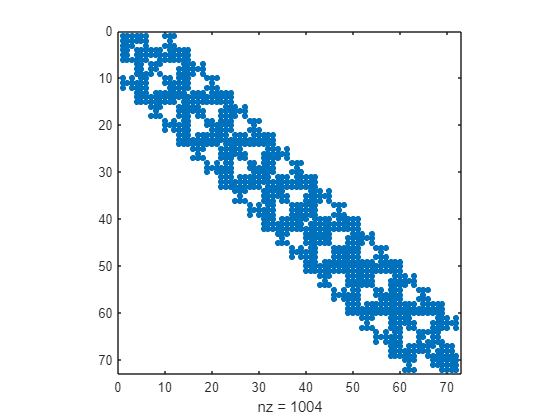

    spy(KT1)
end

## Solution of the Reissner-Mindlin plate problem

### Four-noded bilinear elements

#### Solution of the linear equation system

uQ1 = zeros(numDOFsQ1, 1);
uQ1(freeDOFsQ1) = KQ1(freeDOFsQ1, freeDOFsQ1)\FQ1(freeDOFsQ1);

#### Visualization of the solution in terms of the vertical displacement field

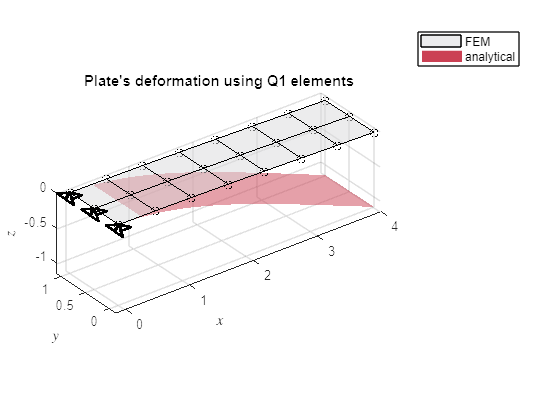

mshCurrQ1W = mshQ1;
scaling = 1;
mshCurrQ1W.nodes(:, 3) = mshCurrQ1W.nodes(:, 3) + ...
    scaling*uQ1(1:3:end);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1W, numVertices, false);
hold on;
fsurf(wEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1W.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical")
title("Plate's deformation using Q1 elements")

#### Visualization of the solution in terms of the rotational field

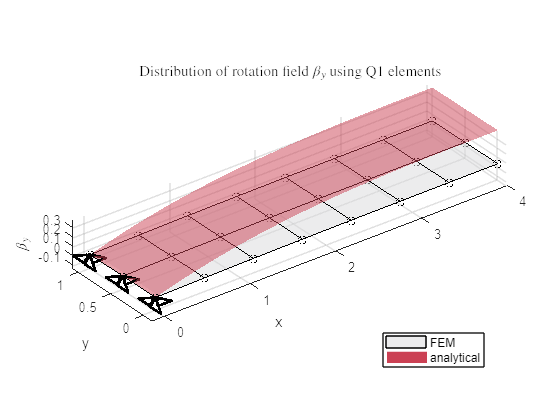

mshCurrQ1BetaY = mshQ1;
scaling = 1;
mshCurrQ1BetaY.nodes(:, 3) = mshCurrQ1BetaY.nodes(:, 3) + ...
    scaling*uQ1(3:3:end);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1BetaY, numVertices, false);
hold on;
fsurf(betaEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1BetaY.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
legend("FEM", "", "analytical", Location="best")
title("Distribution of rotation field $\beta_y$ using Q1 elements", ...
    Interpreter="latex")

### Nine-noded biquadratic elements

#### Solution of the linear equation system

uQ2 = zeros(numDOFsQ2, 1);
uQ2(freeDOFsQ2) = KQ2(freeDOFsQ2, freeDOFsQ2)\FQ2(freeDOFsQ2);

#### Visualization of the solution in terms of the vertical displacement field

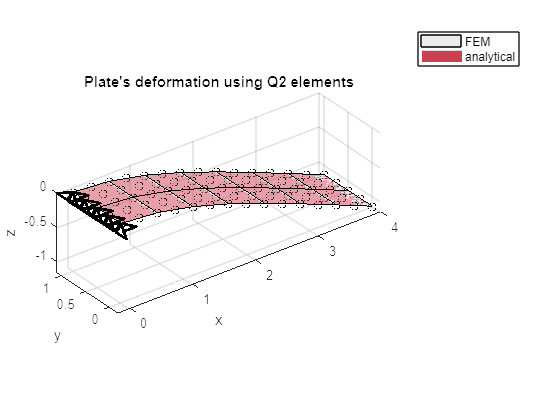

mshCurrQ2 = mshQ2;
scaling = 1;
mshCurrQ2.nodes(:, 3) = mshCurrQ2.nodes(:, 3) + scaling*uQ2(1:3:end);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ2, numVertices, false);
hold on;
fsurf(wEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))    
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")
legend("FEM", "", "analytical")
title("Plate's deformation using Q2 elements")

#### Visualization of the solution in terms of the rotational field

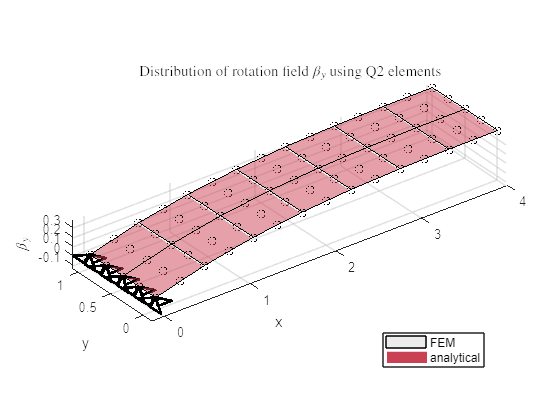

mshCurrQ2BetaY = mshQ2;
scaling = 1;
mshCurrQ2BetaY.nodes(:, 3) = mshCurrQ2BetaY.nodes(:, 3) + ...
    scaling*uQ2(3:3:end);
numVertices = numel(mshQ2.nodes(:, 1));
plotMesh2d(mshCurrQ2BetaY, numVertices, false);
hold on;
fsurf(betaEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2BetaY.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
legend("FEM", "", "analytical", Location="best")
title("Distribution of rotation field $\beta_y$ using Q2 elements", ...
    Interpreter="latex")

### Linear triangular Reissner-Mindlin elements

#### Solution of the linear equation system

if ~isempty(mshT1)
    uT1 = zeros(numDOFsT1, 1);
    uT1(freeDOFsT1) = KT1(freeDOFsT1, freeDOFsT1)\FT1(freeDOFsT1);
end

#### Visualization of the solution in terms of the vertical displacement field

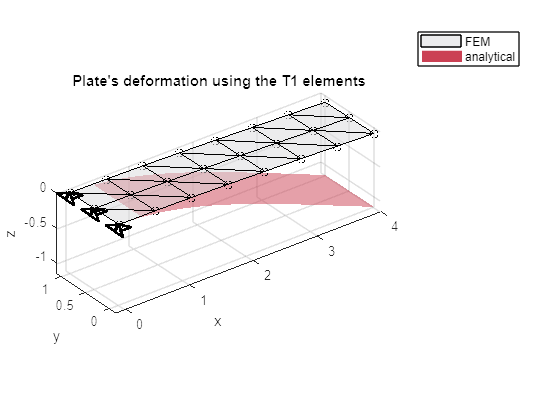

if ~isempty(mshT1)
    mshCurrT1W = mshT1;
    scaling = 1e0;
    mshCurrT1W.nodes(:, 3) = mshCurrT1W.nodes(:, 3) + scaling*uT1(1:3:end);
    numVertices = numel(mshT1.nodes(:, 1));
    plotMesh2d(mshCurrT1W, numVertices, false);
    hold on;
    fsurf(wEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
        FaceAlpha=0.5, LineStyle="none");
    scalVer = 1;
    [xsT1, ysT1, zsT1] = createSupports3D(mshCurrT1W.nodes, homDOFsT1, scalVer);
    for k = 1:length(xsT1(:, 1))
        plot3(xsT1(k, :), ysT1(k, :), zsT1(k, :), 'Linewidth', 2, ...
            'Color', 'black');
    end
    hold off;
    axis equal;
    xlabel("x")
    ylabel("y")
    zlabel("z")
    legend("FEM", "", "analytical")
    title("Plate's deformation using the T1 elements")
end

#### Visualization of the solution in terms of the rotational field

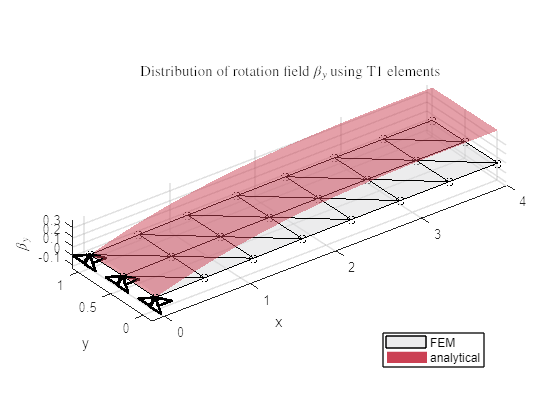

if ~isempty(mshT1)
    mshCurrT1BetaY = mshT1;
    scaling = 1e0;
    mshCurrT1BetaY.nodes(:, 3) = mshCurrT1BetaY.nodes(:, 3) + ...
        scaling*uT1(3:3:end);
    numVertices = numel(mshT1.nodes(:, 1));
    plotMesh2d(mshCurrT1BetaY, numVertices, false);
    hold on;
    fsurf(betaEx, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
        FaceAlpha=0.5, LineStyle="none");
    scalVer = 1;
    [xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrT1BetaY.nodes, homDOFsT1, scalVer);
    for k = 1:length(xsQ2(:, 1))
        plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
            'Color', 'black');
    end
    hold off;
    axis equal;
    xlabel("x")
    ylabel("y")
    zlabel("$\beta_y$", Interpreter="latex")
    legend("FEM", "", "analytical", Location="best")
    title("Distribution of rotation field $\beta_y$ using T1 elements", ...
        Interpreter="latex")
end

  **Try**

Change the thickness in this code section by means of the provided numeric slider without modifying the number of Finite Elements and rerun the script.

 **Reflect**

How do the solutions from these three discretizations, namely, the four-noded bilinear, the nine-noded biquadratic and the three-noded linear, change with respect to the analytical solutions?

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[](https://doi.org/10.1007/978-3-540-78319-0)[[2] Brezzi, F., Boffi, D., Demkowicz, L., Durán, R. G., Falk, R. S., & Fortin, M. (2008). Mixed finite elements, compatibility conditions, and applications. *Springer*, *2*, 4-2.](https://doi.org/10.1007/978-3-540-78319-0)

## **Helper functions**

### **Element Stiffness Matrix and body force vector for quadrilateral elements**

function [Ke, Fe] = ...
    computeElementStiffMatrixandForceVectorReissnerMindlinPlate ...
    (X, N, propStr)

**Function description**

Computation of the element stiffness matrix for an element based on the 2D Reissner-Mindlin plate theory with three degrees of freedom per node $\left(w,\beta_x ,\beta_y \right)$, the vertical deflection and two rotations of the plate's cross section around the X- and the Y-axis, respectively.

**            Input :**

                  `X` : Array containing the nodal coordinates of the nodes in the element

                  `N` : Cell array containing the symbolic expression for the basis functions

      `propStr` : Structure containing the following fields,

                           `.t` : Thickness of the shell

                           `.q` : Distributed load on the shell

                   `.mxBar` : Distributed moment on the beam around x-axis

                   `.myBar` : Distributed moment on the beam around y-axis

                           `.E` : Young's modulus

                         `.nu` : Poisson's ratio

                           `.G` : Shear modulus

                           `.D` : Plate's stiffness

                   `.alpha` : Shear correction factor

**         Output :**

                 `Ke` : Element stiffness matrix of a Reissner-Mindlin shell

                 `Fe` : Element force vector of a Reissner-Mindlin shell

**Function implementation**

Input validation

    arguments
        X (:, 2) double {mustBeReal}
        N (1, :) cell
        propStr (1, 1) struct {mustHaveReissnerMindlinPlateProperties}
    end

Read input

    syms xi eta
    numNodesEl = height(X);
    numDOFsEl = 3*numNodesEl;
    if numel(X(:, 1)) ~= numel(N)
        error("Numner of nodes does not match the number of basis functions");
    end
    if numNodesEl == 4 || numNodesEl == 9
        isQuadMesh = true;
    elseif numNodesEl == 3 || numNodesEl == 7
        isQuadMesh = false;
    else
        error("Visualization for a mesh with elements that have %d " + ...
            "number of nodes is not implemented", numNodes_el);
    end

Computation of the material matrix

    C = [propStr.alpha*propStr.G*propStr.t 0                                 0                    0                     0
         0                                 propStr.alpha*propStr.G*propStr.t 0                    0                     0
         0                                 0                                 propStr.D            propStr.nu*propStr.D  0
         0                                 0                                 propStr.nu*propStr.D propStr.D             0
         0                                 0                                 0                    0                     propStr.D/2*(1 - propStr.nu)];

Formulation of the basis function's matrix

    Nmtx = sym(zeros(3, numDOFsEl));
    for ii = 1:numNodesEl
        Nmtx(1, 3*ii - 2) = N{ii};
        Nmtx(2, 3*ii - 1) = N{ii};
        Nmtx(3, 3*ii) = N{ii};
    end

Formulation of the geometry map

    pos_vct(xi, eta) = transpose([N{:}]*X(:, 1:2));

Formulate the Jacobian matrix

    Jacobian_mtx(xi, eta) = jacobian(pos_vct, [xi eta]);

Compute the determinant of the Jacobian

    detJ(xi, eta) = simplify(det(Jacobian_mtx(xi, eta)));

Compute the derivatives of the basis functions with respect to the physical space in the parametric space

    dNdXY(xi, eta) = simplify(transpose(transpose(Jacobian_mtx(xi, eta)) ...
        \[diff([N{:}], xi); diff([N{:}], eta)]));

Formulate the B-operator matrix for the Reissner-Mindlin plate

    Bmtx = sym(zeros(5, numDOFsEl));
    for ii = 1:numNodesEl
        idx_vct_bf = zeros(1, numel(N));
        idx_vct_bf(1, ii) = 1;
        Bmtx(1, 3*ii - 2) = idx_vct_bf*dNdXY*[1; 0];
        Bmtx(1, 3*ii) = N{ii};
        Bmtx(2, 3*ii - 2) = idx_vct_bf*dNdXY*[0; 1];
        Bmtx(2, 3*ii - 1) = -N{ii};
        Bmtx(3, 3*ii) = idx_vct_bf*dNdXY*[1; 0];
        Bmtx(4, 3*ii - 1) = -idx_vct_bf*dNdXY*[0; 1];
        Bmtx(5, 3*ii - 1) = -idx_vct_bf*dNdXY*[1; 0];
        Bmtx(5, 3*ii) = idx_vct_bf*dNdXY*[0; 1];
    end

Formulate the integrand of the stiffness matrix and the body load vector for the Reissner-Mindlin plate

    KeInt(xi, eta) = transpose(Bmtx)*C*Bmtx*detJ;
    FeInt(xi, eta) = transpose(Nmtx)*...
        [propStr.pBar; propStr.mxBar; propStr.myBar]*detJ;

Compute the stiffness matrix for the Reissner-Mindlin plate

%     Ke = int(int(Ke_integrand, eta, -1, 1), xi, -1, 1);
    Ke = zeros(numDOFsEl);
    if isQuadMesh
        [xiGP, GWXi] = getGaussPointsAndWeightsOverUnitDomain(2);
        [etaGP, GWEta] = getGaussPointsAndWeightsOverUnitDomain(2);
        for jj = 1:height(GWEta)
            for ii = 1:height(GWXi)
                Ke = Ke + KeInt(xiGP(ii), etaGP(jj))*GWXi(ii)*GWEta(jj);
            end
        end
    else
        [GP, GW] = getGaussPointsAndWeightsOnCanonicalTriangle(2);
        numGP = height(GP);
        for ii = 1:numGP
            Ke = Ke + KeInt(GP(2, ii), GP(3, ii))*GW(ii);
        end
    end

Compute the body load vector for the Reissner-Mindlin plate

%     Fe = int(int(Fe_integrand, eta, -1, 1), xi, -1, 1);
    Fe = zeros(numDOFsEl, 1);
    if isQuadMesh
        [xiGP, GWXi] = getGaussPointsAndWeightsOverUnitDomain(2);
        [etaGP, GWEta] = getGaussPointsAndWeightsOverUnitDomain(2);
        for jj = 1:height(GWEta)
            for ii = 1:height(GWXi)
                Fe = Fe + FeInt(xiGP(ii), etaGP(jj))*GWXi(ii)*GWEta(jj);
            end
        end
    else
        [GP, GW] = getGaussPointsAndWeightsOnCanonicalTriangle(2);
        numGP = height(GP);
        for ii = 1:numGP
            Fe = Fe + FeInt(GP(2, ii), GP(3, ii))*GW(ii);
        end
    end

Compute the stiffness matrix and body load vector with double precision

    Ke = double(Ke);
    Fe = double(Fe);

end

## References

[1] Holzer, Stefan, Ernst Rank, and Heinrich Werner. "An implementation of the hp‐version of the finite element method for Reissner‐Mindlin plate problems." *International Journal for Numerical Methods in Engineering* 30.3 (1990): 459-471.